dir = './GOOG.txt';
googleStockData = readtable(dir)

googleStockData = 253×7 table
       Date        Open      High      Low      Close     AdjClose      Volume  
    __________    ______    ______    ______    ______    ________    __________

    2023-07-05    120.06    123.37    120.06    122.63     122.49      1.783e+07
    2023-07-06    120.64    121.15    119.25    120.93     120.79     1.7732e+07
    2023-07-07    120.89    121.75    120.09    120.14        120     2.0982e+07
    2023-07-10    119.07    119.07    116.64    116.87     116.74      3.296e+07
    2023-07-11    116.76    118.22    115.83    117.71     117.58     1.8287e+07
    2023-07-12     119.3    120.96       119    119.62     119.48      2.206e+07
    2023-07-13    121.54    125.33    121.06    124.83     124.69     3.1536e+07
  

dataSet = 1:253

dataSet =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


pastDataModel = fitlm(dataSet([129:253]),googleStockData.Open([129:253]))

pastDataModel = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     84.452       3.1666     26.67    5.7384e-53
    x1             0.38743     0.016291    23.782    7.8015e-48


Number of observations: 125, Error degrees of freedom: 123
Root Mean Squared Error: 6.57
R-squared: 0.821,  Adjusted R-Squared: 0.82
F-statistic vs. constant model: 566, p-value = 7.8e-48

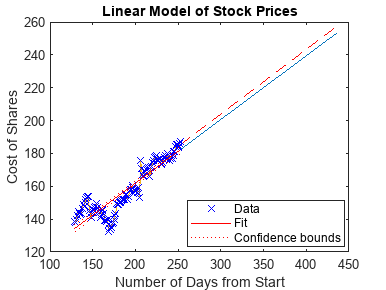


plot(dataSet([129:253]), googleStockData.Open([129:253]))
plot(pastDataModel)
xlabel('Number of Days from Start')
ylabel('Cost of Shares')
title('Linear Model of Stock Prices')

equationCoefficients = polyfit(dataSet([129:253]),googleStockData.Open([129:253]),1)

equationCoefficients =     0.3874   84.4518


m = equationCoefficients(1)

m = 0.3874

b = equationCoefficients(2)

b = 84.4518

x = linspace(253,436)

x =   253.0000  254.8485  256.6970  258.5455  260.3939  262.2424  264.0909  265.9394  267.7879  269.6364  271.4848  273.3333  275.1818  277.0303  278.8788  280.7273  282.5758  284.4242  286.2727  288.1212  289.9697  291.8182  293.6667  295.5152  297.3636  299.2121  301.0606  302.9091  304.7576  306.6061  308.4545  310.3030  312.1515  314.0000  315.8485  317.6970  319.5455  321.3939  323.2424  325.0909  326.9394  328.7879  330.6364  332.4848  334.3333  336.1818  338.0303  339.8788  341.7273  343.5758


y = m * x + b

y =   182.4726  183.1888  183.9049  184.6211  185.3373  186.0534  186.7696  187.4858  188.2019  188.9181  189.6342  190.3504  191.0666  191.7827  192.4989  193.2151  193.9312  194.6474  195.3636  196.0797  196.7959  197.5121  198.2282  198.9444  199.6606  200.3767  201.0929  201.8091  202.5252  203.2414  203.9576  204.6737  205.3899  206.1061  206.8222  207.5384  208.2546  208.9707  209.6869  210.4031  211.1192  211.8354  212.5516  213.2677  213.9839  214.7000  215.4162  216.1324  216.8485  217.5647


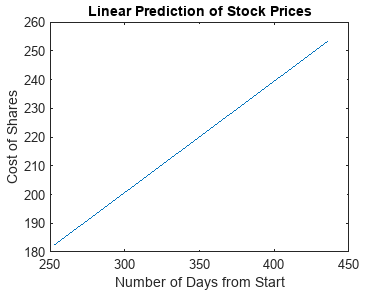

plot(x,y)
xlabel('Number of Days from Start')
ylabel('Cost of Shares')
title('Linear Prediction of Stock Prices')


inflationRate = 0.033

inflationRate = 0.0330

adjustmentFactor = (1 + inflationRate)^(6/12)

adjustmentFactor = 1.0164

yAdjusted = y * adjustmentFactor

yAdjusted =   185.4590  186.1868  186.9147  187.6426  188.3705  189.0984  189.8263  190.5542  191.2820  192.0099  192.7378  193.4657  194.1936  194.9215  195.6494  196.3773  197.1051  197.8330  198.5609  199.2888  200.0167  200.7446  201.4725  202.2003  202.9282  203.6561  204.3840  205.1119  205.8398  206.5677  207.2955  208.0234  208.7513  209.4792  210.2071  210.9350  211.6629  212.3908  213.1186  213.8465  214.5744  215.3023  216.0302  216.7581  217.4860  218.2138  218.9417  219.6696  220.3975  221.1254


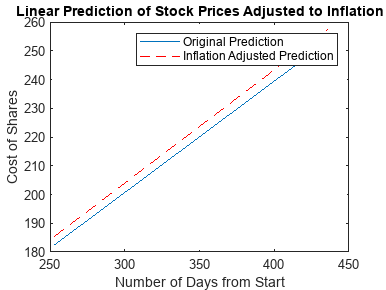

plot(x,y)
hold on
plot(x,yAdjusted,'r--')
xlabel('Number of Days from Start')
ylabel('Cost of Shares')
title('Linear Prediction of Stock Prices Adjusted to Inflation')
legend('Original Prediction', 'Inflation Adjusted Prediction')